# Versuch 5 - Aufschwungsteuerung für das Doppelpendel 

# Praktikum MATLAB®/Simulink® II

## Teilnehmer

#### Teilnehmer 1

Name, Vorname: Gouveia Freitas, Caio Victor

Matrikelnummer: 2328654

#### Teilnehmer 2

Name, Vorname:  Brugnera Silva, Alessandro

Matrikelnummer: 2898524

### Aufgabe 1

Erstellen Sie eine Funktion

*stTraj = berechneTrajektorie(stPendel, Q, R, T)*

edit berechneTrajektorie.m

die aus den Pendeldaten (Struktur wie in Versuch 3 und 4) und der vorzugebenden Übergangszeit $T$ die Verläufe der Eingangsgröße $u^* \left(t\right)$ und der Zustände ${\mathbf{x}}^* \left(t\right)$ nach dem vorgestellten Verfahren mit *bvp4c* berechnet. Es bietet sich an, als Rückgabewert eine Struktur zu haben, in denen der Zeitvektor $t$ mit der Steuerfolge $u$ und den Zuständen $\mathbf{x}$ zurückgegeben werden. $u$ lässt sich aus (17.9) aus dem Skript berechnen. Außerdem könnte noch explizit die Übergangszeit $T$ angegeben werden: 


$$\begin{array}{l}
\mathrm{stTraj}\ldotp T\\
\;\;\;\;\;\;\;\;\;\;\;\;\ldotp \mathrm{vT}\\
\;\;\;\;\;\;\;\;\;\;\;\;\ldotp \mathrm{vU}\\
\;\;\;\;\;\;\;\;\;\;\;\;\ldotp \mathrm{mX}
\end{array}$$


Um diese Funktion zu realisieren, können Sie sich an folgenden Schritten orientieren:

1.Gegeben ist eine Funktion RandwertproblemDGL, die das DGL-System (17.6), (17.7) und (17.8) aus dem Skript des Randwertproblems beschreibt:

*dx = RandwertproblemDGL(t, x, stPendel, Q, R)*

Die Funktion hat als Eingangsparameter zum eine die von bvp4c geforderten Daten: Zeit $t$ und Zustandsvektor $\mathbf{x}$. Zudem sollen dieser Funktion auch die Struktur mit den Pendeldaten und die $\mathbf{Q}$ und $R$ übergeben werden können. Da *bvp4c* nur die ersten zwei Parameter benutzt, würde dies zum Absturz führen, d. h. es muss möglich sein, diese Funktion auch mit zwei Parametern aufzurufen. Im Abschnitt 18.3 im Skript wurden dazu zwei Möglichkeiten vorgestellt, von denen Sie sich eine aussuchen können. Stimmen Sie die Funktion *RandwertproblemDGL* entsprechend auf Ihre Wahl ab und vervollständigen Sie die Funktion.

2.Schreiben Sie eine Funktion

*deltaRB = RandwertproblemRB(xa, xb).*

%edit RandwertproblemRB.m

Sie gibt einen Spaltenvektor *deltaRB* mit der Abweichung der Werte bei $t=0$ und $t=T$ zu den gegebenen Randwerten aus (17.1) im Skript zurück.

3.Erstellen Sie in der Funktion *berechneTrajektorie* die Struktur *solinit* mit den Startwerten für den Löser. Geben Sie zunächst eine Aufteilung für $t$ in 1000 Intervallen an. Für $\mathbf{y}\left(t\right)$ geben Sie den linearen Verlauf der beiden Zustände von Anfangs- zum Endwert vor.

4.Lösen sie das Randwertproblem mit *bvp4c*. Eine Warnung bei *bvp4c* bedeutet sehr  wahrscheinlich, dass die Lösung noch nicht gefunden wird. Man kann die berechnete Lösung als Anfangswert für *bvp4c* wieder verwenden. Dies kann man solange wiederholen, bis eine Lösung gefunden wird. Stellen Sie dabei die relative Fehlertoleranz von *bvp4c* auf ${\textrm{10}}^{-10}$ ein, um eine richtige Lösung zu finden.

- Als einfachste, hier aber ausreichende Lösung können Sie einfach eine Schleife programmieren, die *bvp4c* fünfzehn mal aufruft.

- Sie könnten dabei noch den Rückgabewert von *bvp4c* auswerten, um festzustellen, ob das Randwertproblem (wahrscheinlich) gelöst wurde. Falls ja, können Sie die Schleife abbrechen.

- Sie könnten Ihre Funktion auch dahingehend erweitern, dass man die letzte Trajektorie als neuen Startwert übergeben kann. Dazu müsste die Trajektorenstruktur ein weiteres Feld mit der Lösung von *bvp4c* erhalten, damit der Verlauf der Lagrange’schen Multiplikatoren nicht jedes mal neu berechnet werden muss. (Damit könnte man auch einen Startwert aus der Lösung für die zuvor bestimmte Trajektorie für ein anderes $T$ generieren. So müsste der Löser nicht „bei Null“ anfangen.)

- Alternativ bzw. zusätzlich können Sie die Parameter von *bvp4c* verändern und betrachten, wie diese die Lösungsfindung beeinflussen.

Berechnen bzw. entnehmen Sie aus der von *bvp4c* zurückgegebenen Struktur den Verlauf für die Eingangsgröße $u^* \left(t\right)$ sowie den Verlauf aller vier Zustände ${\mathbf{x}}^* \left(t\right)$ und geben Sie diese in der oben angegebenen Struktur *stTraj* zurück.

#### Ihre Antwort:

Keine Antwort notwendig!

**Code und Plots zu Ihrer Antwort:**

% Kein Code erforderlich!

### Aufgabe 2

- Wählen Sie zunächst $\mathbf{Q}=\textrm{diag}\left(\left\lbrack \begin{array}{cccc}
1 & 1 & 1 & 1
\end{array}\right\rbrack \right)$ und $R=10$.

- Wählen Sie für $T$ einen Wert zwischen 0,1 und 2 s.

- In welchem Wertebereich für $T$ können Lösungen gefunden werden? Versuchen Sie den Wertebereich zu erklären.

- Finden Sie die kleinste $T$, bei der die Beschränkung ${\left|M\right|}_{\max } =2\;\textrm{Nm}$ eingehalten wird.

- Plotten sie den Verlauf der Zustände ${\mathbf{x}}^* \left(t\right)$ und der Stellgröße $M\left(t\right)$ für verschiedene Übergangszeiten $T$ (3 verschiedene inkl. der besten). Erklären Sie die Auswirkung der Übergangszeiten $T$ auf das Ergebnis.

#### Ihre Antwort:

**Code und Plots zu Ihrer Antwort:**

Q=eye(4);
R=10;

T = 0.1000

T=0.1
stPendel=ladePendel;


stTraj = struct with fields:
    T: [1×1000 double]


odefun = function_handle with value:
    @(t,x)RandwertproblemDGL(t,x,stPendel,Q,R)


stTraj = struct with fields:
    solver: 'bvp4c'
         x: [1×1000 double]
         y: [8×1000 double]
        yp: [8×1000 double]
     stats: [1×1 struct]


sol = struct with fields:
    solver: 'bvp4c'
         x: [1×1000 double]
         y: [8×1000 double]
        yp: [8×1000 double]
     stats: [1×1 struct]


sol=berechneTrajektorie(stPendel,Q,R,T)
ax1 = subplot(2,1,1);
plot(sol.x,sol.y(1,:),'b')
hold on
plot(sol.x,sol.y(3,:),'r')
hold off;
legend({'phi1','phi2'},'Location','northwest')
subplot(2,1,2);
plot(sol.x,sol.y(2,:),'b')
hold on
plot(sol.x,sol.y(4,:),'r')
hold off;
legend({'dphi1','dphi2'},'Location','northwest')
T=2;
stPendel=ladePendel;


stTraj = struct with fields:
    T: [1×1000 double]


odefun = function_handle with value:
    @(t,x)RandwertproblemDGL(t,x,stPendel,Q,R)


stTraj = struct with fields:
    solver: 'bvp4c'
         x: [1×1000 double]
         y: [8×1000 double]
        yp: [8×1000 double]
     stats: [1×1 struct]


sol = struct with fields:
    solver: 'bvp4c'
         x: [1×1000 double]
         y: [8×1000 double]
        yp: [8×1000 double]
     stats: [1×1 struct]


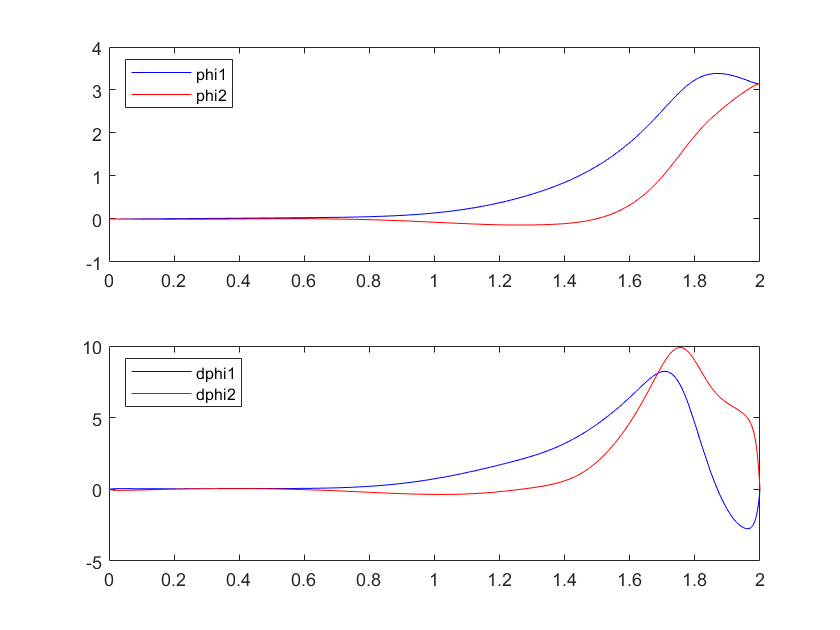

sol=berechneTrajektorie(stPendel,Q,R,T)
ax1 = subplot(2,1,1);
plot(sol.x,sol.y(1,:),'b')
hold on
plot(sol.x,sol.y(3,:),'r')
hold off;
legend({'phi1','phi2'},'Location','northwest')
subplot(2,1,2);
plot(sol.x,sol.y(2,:),'b')
hold on
plot(sol.x,sol.y(4,:),'r')
hold off;

legend({'dphi1','dphi2'},'Location','northwest')

### Aufgabe 3

- Bauen Sie die Steuerung unter Simulink auf. Dazu ist das Simulink Modell *Aufschwungsteuerung.slx gegeben.* Benutzen Sie die s-Function *systemPendel_V3* als Modell für das System. Achten Sie auf den Endwert von der berechneten $M$. Dieser muss im oberen Arbeitspunkt ($\varphi_1 =\pi$ und $\varphi_2 =\pi$) identisch zu $M_{\textrm{AP}}$ sein. Bauen Sie das Simulink-Modell daher so auf, dass $M_{\textrm{AP}}$ nach dem Zeitpunkt $T$ die Stellgröße übernimmt. 

- Stellen Sie den solver von Simulink auf *ode45* und die relative Toleranz auf ${10}^{-10}$ ein.

open_system('Aufschwungsteuerung.slx')

#### Ihre Antwort:

Keine Antwort notwendig!

**Code und Plots zu Ihrer Antwort:**

% Kein Code erforderlich!

### Aufgabe 4

- Gehen Sie von $T=1$ aus.

- Vergleichen Sie anhand von Zeitplots das Ergebnis der Simulation mit den theoretisch berechneten Trajektorien. Lassen Sie die Simulation etwa eine Sekunde länger als die Übergangszeit $T$ laufen. 

- Variieren Sie bei der Simulation auch die Pendelparameter (3 Beispiele). Berechnen Sie jedoch keine neue Steuerung! Schafft die berechnete Trajektorie immer noch das Doppelpendel in die obere Ruhelage zu bringen? Plotten Sie die Simulationsergebnisse, um Ihre Aussage zu unterstützen.

#### Ihre Antwort:

**Code und Plots zu Ihrer Antwort:**

# Wichtige Anmerkung

**Strukturieren Sie ihren Code so, dass jede Sektion für sich ausführbar ist, und keine vorhergehenden Funktionen notwendig sind!** Muss beispielsweise ein Modell in mehreren aufgaben geladen werden, so laden Sie es in jedem Abschnitt erneut, insoweit nichts anderes angegeben ist.

Der Versuchsbericht in Form **dieses** Live Scriptes (einer pro Gruppe) ist anhand der oben aufgeführten Fragen anzufertigen und mit allen benötigten Funktionen innerhalb von einer Woche bei Moodle als Zip-File hochzuladen. Dafür ist eine sogenannte Datenbank bei Moodle hinterlegt. Bitte beachten Sie die zeitliche Begrenzung bis wann Sie die Unterlgen hochladen können. Wird ein Versuch nicht hochgeladen ist eine weitere Teilnahme am Praktikum nicht möglich. 

Bei jeder Aufgabe, in der eine Programmierung oder ein Skriptaufruf erforderlich ist, ist ein Codebereich definiert, indem sie alle notwendigen Befehle aufrufen können. Dieser Berich wird nicht bewertet. Alternativ können Sie ihre Zwischenrechnungen natürlich im Commandwindow oder in einem externen Skript aufrufen.

Ihre Textantworten sind stehts unter den Punkt ***Ihre Antwort****:* anzugeben. Antworten an anderer Stelle werden nicht bewertet!

Wird nach zu programmierenden Funktionen gefragt, ist ein Codefeld (bspw. *edit initModell.m*) hinterlegt, welches ein Grundgerüst zur Funktion aufruft. 

Im Praktikum kann es dazu kommen, dass Matrizen abgefragt werden. Im Bereich ***Code und Plots zu Ihrer Antwort ***sind die Variablen vordefiniert, jedoch ohne Inhalt. An dieser Stelle sind die Matrizen **ausgeschrieben** einzutragen. Bspw. berechnen Sie über eine Funktion eine Matrix $\left\lbrack \begin{array}{cc}
2 & 1\\
3 & 4
\end{array}\right\rbrack$. Diese ist dann im dafür vorgesehenen Codefeld ***Code und Plots zu Ihrer Antwort ***bei der passenden Variablen einzufügen. Beispiel:

% Vorgabe
A_vorgabe = -inf;
% Eigene Lösung
A_vorgabe = [2, 1; 3, 4];

Die Auswertung erfolgt teilautomatisiert.** Daher sind die Variablen auf keinen Fall umzubenennen.**

Sind Plots anzufertigen, wird danach explizit gefragt. Dabei sollte ein besonderer Wert auf die Aussagekraft der Diagramme und der Screenshots gelegt werden. Die Plots ***Code und Plots zu Ihrer Antwort ***sollen im Feld erstellt werden. Achten Sie darauf, dass sie einen neuen Plot stehts mit dem keyword *figure* neu beginnen. In der Regel ist dies jedoch vorgegeben.

Skalieren Sie die Diagramme sinnvoll, so dass das Ablesen bzw. Erkennen der interessierenden Größen möglich ist. In den Diagrammen ist eine eindeutige Achsenbezeichnung mit entsprechenden Größen und Einheiten unabdingbar. Bedenken Sie bei der Erstellung der Diagramme, dass diese auch schwarz/weiß ausgedruckt gut erkennbar und die einzelnen Graphen unterscheidbar sein müssen. Strukturieren Sie die Protokolle so, dass auch nach einer längeren Zeitpause ein rascher Einstieg in die Thematik möglich ist. Dies kann im späteren Berufsleben eine erhebliche Zeitersparnis mit sich bringen.

Eines der wichtigsten Hilfsmittel ist das Sektionsweise aufrufen. Das Live Script ist in Sektionen unterteilt. Diese können jeweils über den Punkt *Run Section* im oberen Bereich der Matlab Toolbar unter dem Punkt *Live Editor* oder per Tastenkombination **Strg + Enter **ausgeführt werden.

## Platz für Funktionen

## Platz für persönliche Hilfsfunktionen